# El Mapa Logístico

## 
$$x_{n+1} =\mu \;x_n \left(1-x_n \right)$$
 

## Puntos Fijos

Para encontrar los puntos fijos del mapa, $x^*$, igualamos $x_{n+1}$ a $x_n$:


$$\mu \;x^* \left(1-x^* \right)=x^* \;$$


Resolviendo esta ecuación, obtenemos:

${x_1 }^* =0$  y  ${x_2 }^* =\frac{\;\mu -1}{\mu \;}$

## Estabilidad

Para determinar la estabilidad de estos puntos fijos, necesitamos evaluar la derivada del mapa discreto en cada punto fijo. La derivada del mapa es: $f^{\prime } \left(x_n \right)=\mu \;-2\mu \;x_n$

- Para ${x_1 }^* =0$, $f^{\prime } \left({x_1 }^* \right)=\mu \;,$ entonces el punto fijo es estable si $\mu <1$, e inestable si $\mu >1$.

- Para ${x_2 }^* =\frac{\;\mu -1}{\mu \;}$, $f^{\prime } \left({x_2 }^* \right)=2-\mu \;$, entonces, el punto fijo es estable cuando $1<\mu <3$

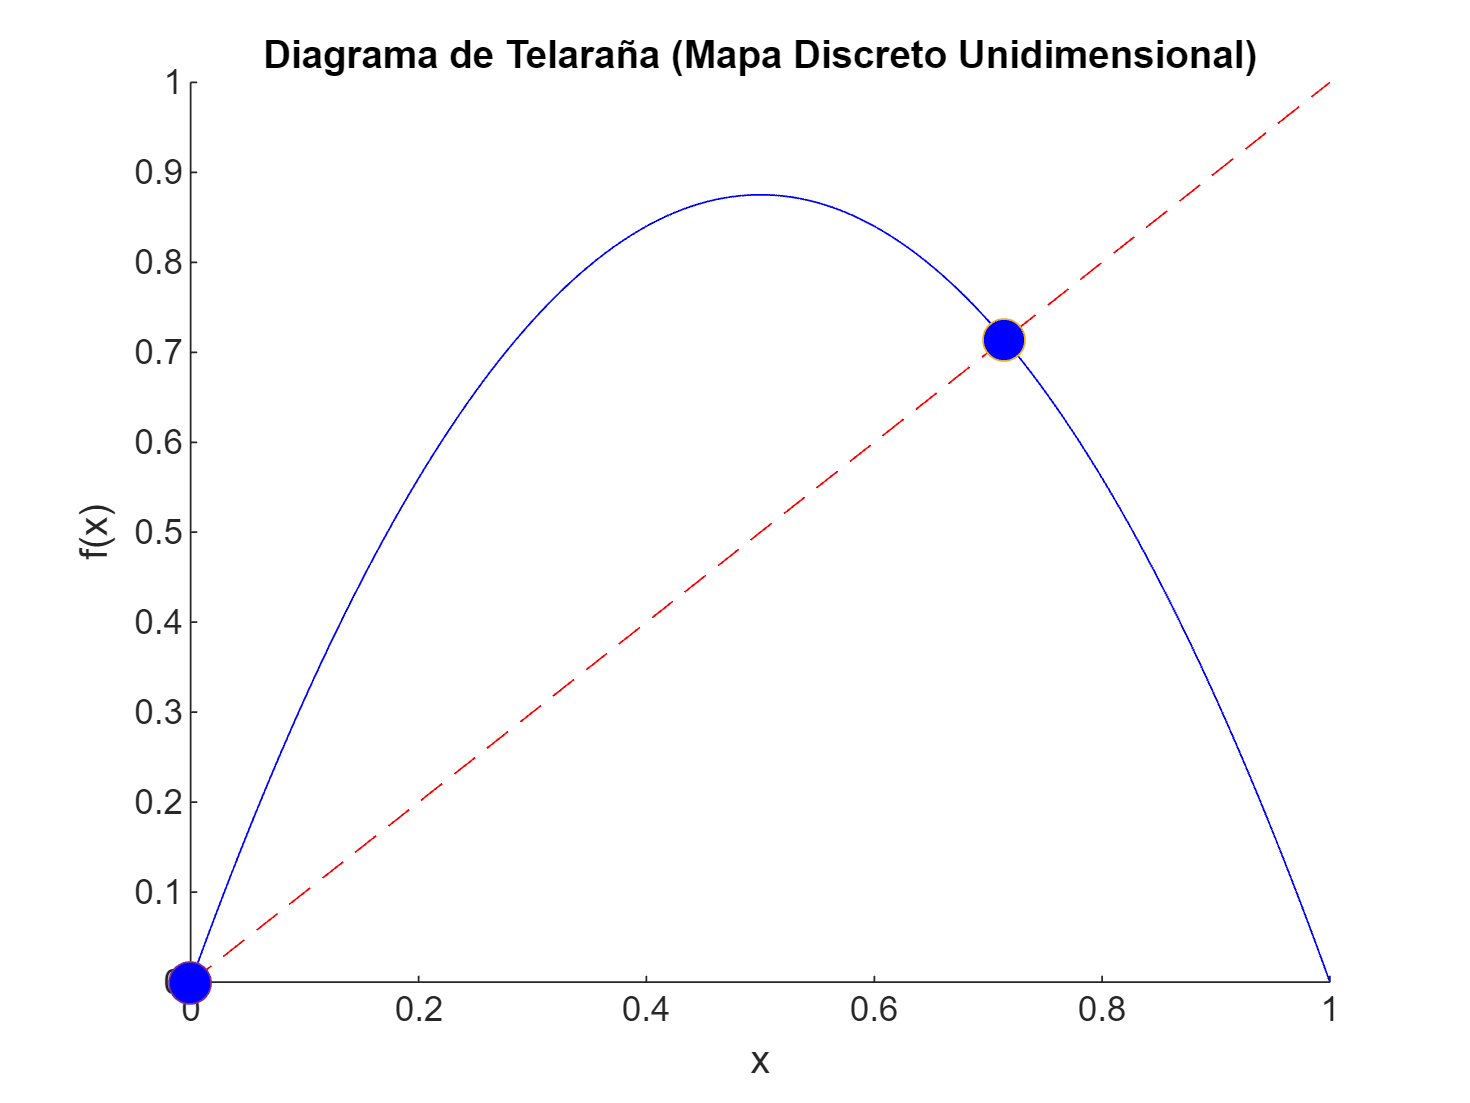

% Definir la función del mapa logístico
logistic = @(x, mu) mu *x.*(1 - x);

% Definición de parámetros
mu = 3.5; % Parámetro de crecimiento de la población
% el puntode equilibrio x2_star
xstar = (mu-1)/mu;

% Definir el rango de valores para x y el número de iteraciones
x_range = linspace(0, 1, 1000);
num_iterations = 500;

% Visualizar el diagrama de telaraña
figure;hold on;
% Dibujar la función del mapa discreto
plot(x_range, logistic(x_range,mu), 'b');
xlabel('x');
ylabel('f(x)');
% Dibujar la línea diagonal y=x
plot(x_range, x_range, 'r--');
plot(xstar,logistic(xstar,mu),'o','MarkerSize',12,'MarkerFaceColor','b')
plot(0,logistic(0,mu),'o','MarkerSize',12,'MarkerFaceColor','b')
title('Diagrama de Telaraña (Mapa Discreto Unidimensional)');

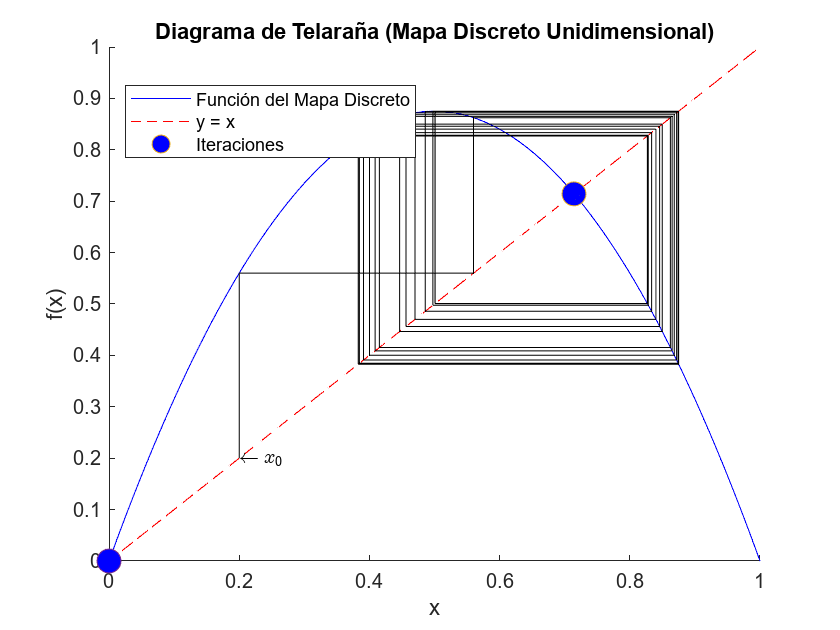

% Visualizar el diagrama de telaraña
x_init = .2; % Punto inicial arbitrario
text(x_init, x_init, '$\leftarrow x_0$', 'HorizontalAlignment', 'left','Interpreter','latex');
for i = 1:num_iterations
    x_next = logistic(x_init,mu);
    mapa(i)=x_next;
    % Trazar la línea que conecta los puntos (x, f(x)) y (f(x), f(x))
    plot([x_init, x_init], [x_init, x_next], 'k'); % línea vertical
    plot([x_init, x_next], [x_next, x_next], 'k'); % línea horizontal        
    x_init = x_next;
    drawnow;
end
legend('Función del Mapa Discreto', 'y = x', 'Iteraciones','Location', 'southwest');
legend("Position", [0.15133,0.74997,0.34107,0.11476])

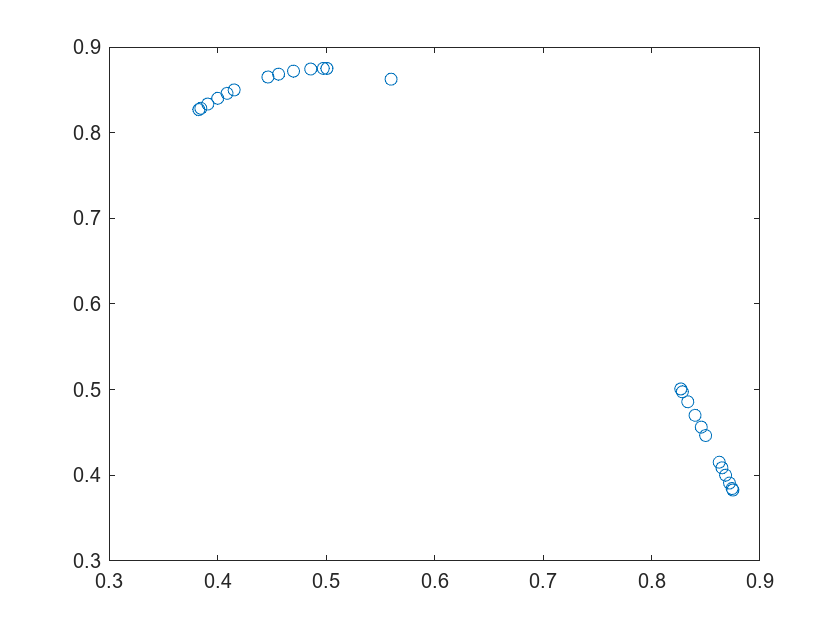

figure;
plot(mapa(1:end-1),mapa(2:end),'o')